# Inverted Pendulum

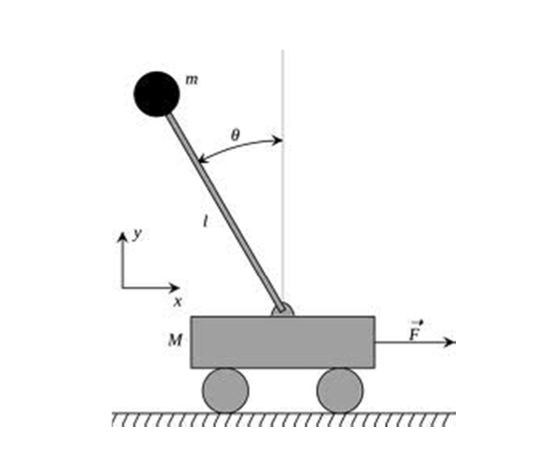

Equtions of Motion


$$\left(M+m\;\right)\ddot{x} -\left(ml\ddot{\theta} \cos \left(\theta \right)-ml{\dot{\theta} }^2 \sin \left(\theta \right)\;\right)=F\left(t\right)$$



$$l\ddot{\theta} -\ddot{x} \cos \left(\theta \right)-\mathrm{gsin}\left(\theta \right)=0$$


Lineratilized equatiosn u(t) is input force


$$M\ddot{x} +m\ddot{l\theta } -u\left(t\right)=0$$



$$\;\ddot{x} +l\ddot{\theta} -g\theta =0$$


State Space Linear Model the form $\dot{x} =A\;x+B$


$$\left\lbrack \begin{array}{c}
\dot{x} \\
\ddot{x} \\
\dot{\theta} \\
\ddot{\theta} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & 0 & \frac{-m\;g}{M} & 0\\
0 & 0 & 0 & 1\\
0 & 0 & \frac{g}{l} & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\dot{x} \\
\theta \\
\dot{\theta} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{1}{M}\\
0\\
\frac{-1}{M\;l}
\end{array}\right\rbrack \;u\left(t\right)\;$$


Output Theta


$$y=C\;x+D\;u$$



$$y=\left\lbrack \begin{array}{cccc}
0 & 0 & 1 & 0
\end{array}\right\rbrack$$

$$\left\lbrack \begin{array}{c}
x\\
\dot{x} \\
\theta \\
\dot{\theta} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0
\end{array}\right\rbrack \cdot u$$
 

clc
% Paramters
mp = 0.5; % Mass of Pendulum [kg]
mc = 0.3; % Mass of Cart [kg]
l = 0.15; % Lenght of Pole [m]
d1 = 1e-2; % Dampening on Cart Displacement
d2 = 1e-2; % Dampentin on Joint 
g = 9.81; % Gravity

% State Space Matricies
x0 = [0 ; 5*pi/180; 0; 0];

A = [0, 1,          0, 0; 
     0, 0, -(mp*g)/mc, 0;
     0, 0,          0, 1;
     0, 0,        g/l, 0];

B = [0 ; 1/mc ; 0 ; -1/(mc*l)];

%Output
C = [1 0 0 0];
D = 0

D = 0

% Vecirfy System
sys = ss(A, B, C, D)

sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0  -16.35       0
   x3       0       0       0       1
   x4       0       0    65.4       0
 
  B = 
           u1
   x1       0
   x2   3.333
   x3       0
   x4  -22.22
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


poles =  eig(A)

poles =          0
         0
    8.0870
   -8.0870


Sc = ctrb(sys)

Sc = 1.0e+03 *

         0    0.0033         0    0.3633
    0.0033         0    0.3633         0
         0   -0.0222         0   -1.4533
   -0.0222         0   -1.4533         0


So = obsv(sys)

So =     1.0000         0         0         0
         0    1.0000         0         0
         0         0  -16.3500         0
         0         0         0  -16.3500


controlability = rank(Sc)

controlability = 4

observability = rank(So)

observability = 4

% Controller
Q =  C'*C;
R = 1;
K = lqr(A,B,Q,R)

K =     1.0000    1.1571   -7.3214   -0.6464


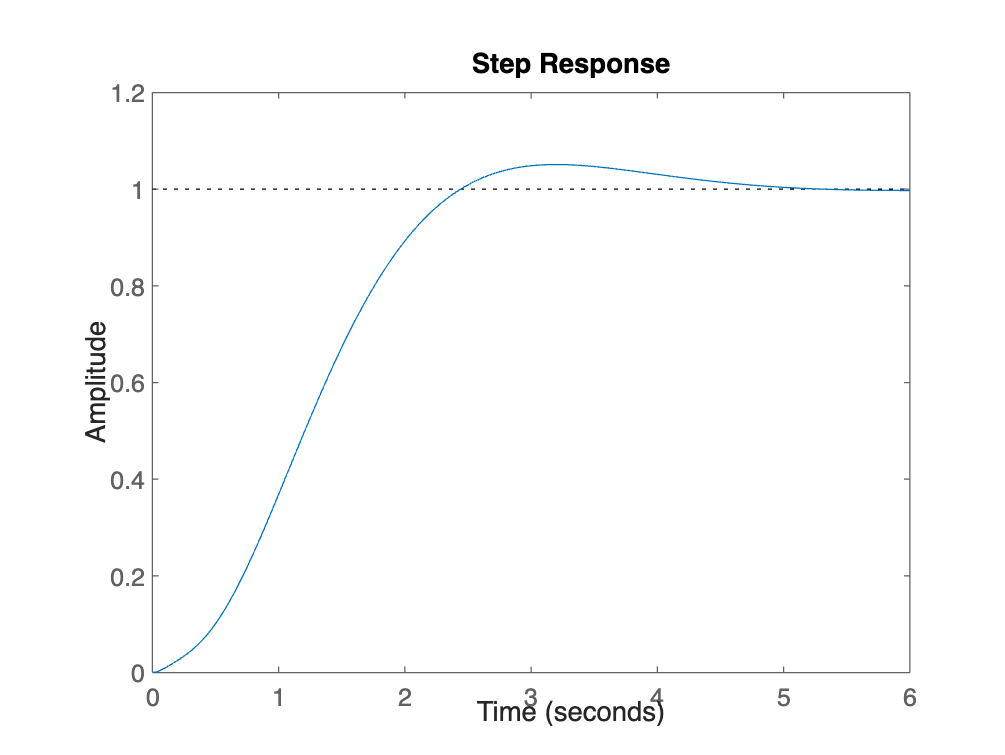


Ac = (A-B*K);
Bc = B;
Cc = C;
Dc = D;

sys_cl = ss(Ac, Bc,Cc, Dc);

step(sys_cl)